# 01 Homework: Discrete System 

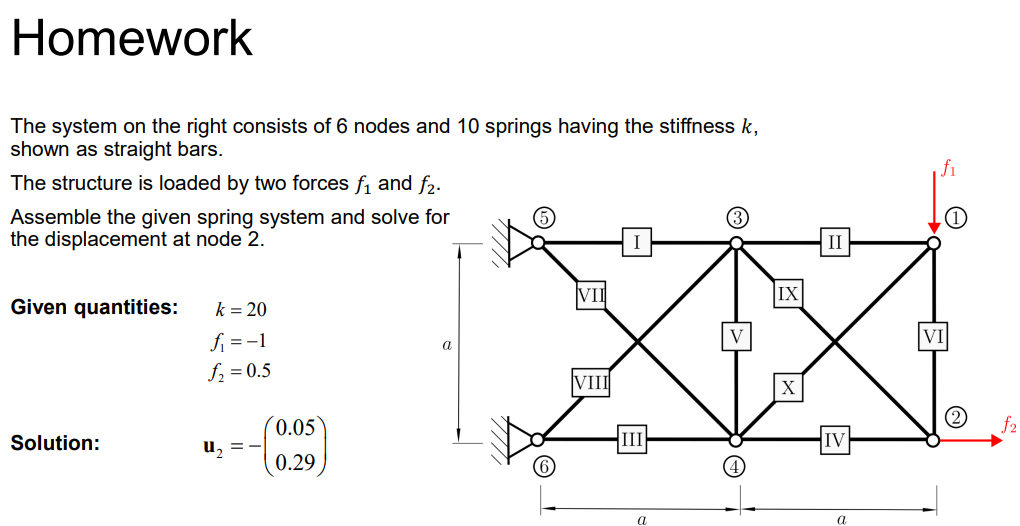

clear all; clc; close all;

% Set up spring stiffness matrixes and assemble global stiffness matrix
connectivity = [9 10 5 6;
                5 6 1 2;
                11 12 7 8;
                7 8 3 4;
                5 6 7 8;    % what if I switch?!
                1 2 3 4;    % same (maybe okay with angles)
                9 10 7 8;
                11 12 5 6;
                5 6 3 4;
                7 8 1 2];

angles = [0, 0, 0, 0, -90,-90 -45, 45, -45, 45];

KEL = [ 1 -1; 
       -1  1];
k = 20;
K = zeros(12);

for beam = 1 : 10

    edof    = connectivity(beam, :);
    TE      = transformationMatrix(angles(beam));
    KE      = k * TE' * KEL * TE;
    
    K(edof, edof) = K(edof, edof) + KE;

end
K

K =    30.0000   10.0000         0         0  -20.0000         0  -10.0000  -10.0000         0         0         0         0
   10.0000   30.0000         0  -20.0000         0         0  -10.0000  -10.0000         0         0         0         0
         0         0   30.0000  -10.0000  -10.0000   10.0000  -20.0000         0         0         0         0         0
         0  -20.0000  -10.0000   30.0000   10.0000  -10.0000         0         0         0         0         0         0
  -20.0000         0  -10.0000   10.0000   60.0000         0         0         0  -20.0000         0  -10.0000  -10.0000
         0         0   10.0000  -10.0000         0   40.0000         0  -20.0000         0         0  -10.0000  -10.0000
  -10.0000  -10.0000  -20.0000         0         0         0   60.0000         0  -10.0000   10.0000  -20.0000         0
  -10.0000  -10.0000         0         0         0  -20.0000         0   40.0000   10.0000  -10.0000         0         0
         0         0        

% Force vector and solution
u = zeros(12, 1);
f = zeros(12, 1);

f(2) = -1;
f(3) = 0.5;

fixeddof = [9,10,11,12];
freedof = setdiff(1 : 12, fixeddof);

u(freedof) = K(freedof, freedof) \ f(freedof);

u(3:4)

ans =    -0.0532
   -0.2877


function T = transformationMatrix(angle)
    % Returns transformation matrix for two local degrees of freedom to global 2D system
    % INPUT
    %   angle (float)   Rotation angle in degrees
    T = [cosd(angle), sind(angle), 0, 0;
        0, 0, cosd(angle), sind(angle)];
end